clear; clc; close all;

%% =========================
% Zero joint position
% All joint angles are in radians
%% =========================
q = [pi/4 6 0 0 0];

%% =========================
% Robot dimensions (replace with your own values)
%% =========================
b  = 2.5;
L1 = 5;
L2 = 18;
L3 = 12;
L4 = 6;

%% =========================
% Standard DH table
% Each row = [a_{i-1}, alpha_{i-1}, d_i, theta_i]
%% =========================
DH_table = [ ...
   -b,   pi/2,   L1,      q(1);
    L2,    0,     0,      q(2) + pi/2;
    L3,    0,     0,      q(3);
     0,   -pi/2,  0,      pi - q(2) - q(3) - pi/2;
     0,    0,    L4,      q(1)
];

%% =========================
% Forward kinematics
%% =========================
n = size(DH_table,1);

T = eye(4);                  % cumulative transform
origins = zeros(3,n+1);      % O0 to On
origins(:,1) = [0;0;0];      % base origin

T_all = cell(1,n);           % store cumulative transforms

for i = 1:n
    a     = DH_table(i,1);
    alpha = DH_table(i,2);
    d     = DH_table(i,3);
    theta = DH_table(i,4);

    A_i = DH_std(a, alpha, d, theta);   % A_i = T_{i-1}^{i}
    T = T * A_i;                        % cumulative transform

    T_all{i} = T;
    origins(:,i+1) = T(1:3,4);
end

%% =========================
% Display final end-effector transform
%% =========================
disp('Final transformation matrix T_0^E at zero position:');

Final transformation matrix T_0^E at zero position:


disp(T);

   -1.0000         0   -0.0000    4.1595
         0    1.0000   -0.0000    4.1595
   -0.0000   -0.0000   -1.0000   27.8051
         0         0         0    1.0000



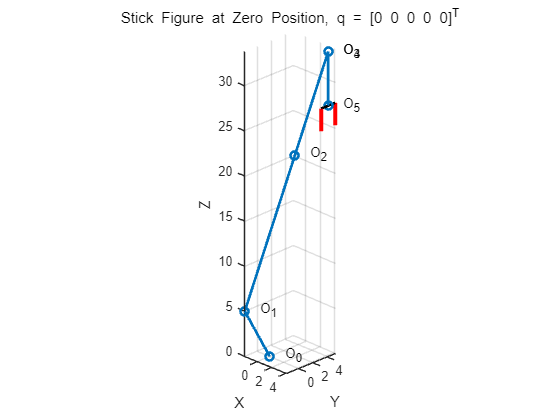


%% =========================
% Plot stick figure
%% =========================
figure;
plot3(origins(1,:), origins(2,:), origins(3,:), '-o', ...
      'LineWidth', 2, 'MarkerSize', 6);
grid on; axis equal;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Stick Figure at Zero Position, q = [0 0 0 0 0]^T');

hold on;
for i = 1:(n+1)
    text(origins(1,i), origins(2,i), origins(3,i), sprintf('  O_%d', i-1));
end

%% =========================
% Draw gripper at Frame 5
% Opening along z5, separated along y5
%% =========================
T5 = T_all{5};   % transform of frame 5 wrt base

finger_length = 2.5;
finger_offset = 1;

% In frame 5:
% two fingers located at y5 = +1 and y5 = -1
% each finger extends along +z5 direction

p1_base_5 = [0;  finger_offset; 0; 1];
p1_tip_5  = [0;  finger_offset; finger_length; 1];

p2_base_5 = [0; -finger_offset; 0; 1];
p2_tip_5  = [0; -finger_offset; finger_length; 1];

% Transform to base frame
p1_base_0 = T5 * p1_base_5;
p1_tip_0  = T5 * p1_tip_5;

p2_base_0 = T5 * p2_base_5;
p2_tip_0  = T5 * p2_tip_5;

% Plot the two fingers
plot3([p1_base_0(1), p1_tip_0(1)], ...
      [p1_base_0(2), p1_tip_0(2)], ...
      [p1_base_0(3), p1_tip_0(3)], ...
      'r', 'LineWidth', 3);

plot3([p2_base_0(1), p2_tip_0(1)], ...
      [p2_base_0(2), p2_tip_0(2)], ...
      [p2_base_0(3), p2_tip_0(3)], ...
      'r', 'LineWidth', 3);

% Optional: connect the two finger bases
plot3([p1_base_0(1), p2_base_0(1)], ...
      [p1_base_0(2), p2_base_0(2)], ...
      [p1_base_0(3), p2_base_0(3)], ...
      'k', 'LineWidth', 2);



view(45,25);

function T = DH_std(a, alpha, d, theta)
% Standard DH transform using [a_{i-1}, alpha_{i-1}, d_i, theta_i]

T = [cos(theta), -sin(theta)*cos(alpha),  sin(theta)*sin(alpha), a*cos(theta);
     sin(theta),  cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
     0,           sin(alpha),             cos(alpha),            d;
     0,           0,                      0,                     1];
end
